# Yaw Parameter Estimation

This lab shows how to find the thrust gain and damping parameter of the yaw-only system (i.e., pitch is locked). 

## Concept Review

The AERO 2 yaw-axis only model can be represented by the equation of motion 


$$J_y \ddot{\psi}(t) + D_y \dot{\psi}(t) = K_{yy} D_t V_y$$


where $\psi$ is the yaw angle, $J_y$ is the equivalent moment of inertia acting about the yaw axis, $D_y$ is the viscous damping, $K_{yy}$ is the force thrust gain, $D_t$ is the distance from the pivot point to the propeller, $V_y$ is the voltage applied to the rear/yaw rotor motor. 

Based on the EOM, we have the folloiwng transfer function


$$\Psi(s) = \frac{K_{yy}D_tV_y(s)}{J_y s^2+D_y s}$$


In this lab we apply a yaw step voltage to measure yaw thrust, $K_{yy}$, and damping, $D_y$. The moment of inertia, $J_y$, is known.

## Lab Procedure

Apply a step voltage to the rear.yaw rotor to measure the thrust gain and then set it to 0V to measure the free-oscillation decaying response to measure the damping. 

### Setup

- Make sure the Aero 2 has been tested as instructed in the Quick Start Guide. 

- Launch MATLAB and browse to the working directory that includes the Simulink models for this lab.

- Configure the Aero 2 in the 2 DOF Helicopter configuration: 

- **Lock** the pitch axis and **unlock **the yaw axis.

- Rear rotor 1 is **vertical **and front rotor 0 is **horizontal**.

- Mount weight on each rotor.

- Connect the USB cable to your PC/laptop.

- Connect the power and turn the power switch ON. The Aero base LED should be red

Load the AERO 2 Parameters

aero2_parameters;

### Lab 1: Get Open-Loop Response

The open-loop response can be obtained by running the `q_aero2_yaw_step `Simulink model shown below in QUARC. 

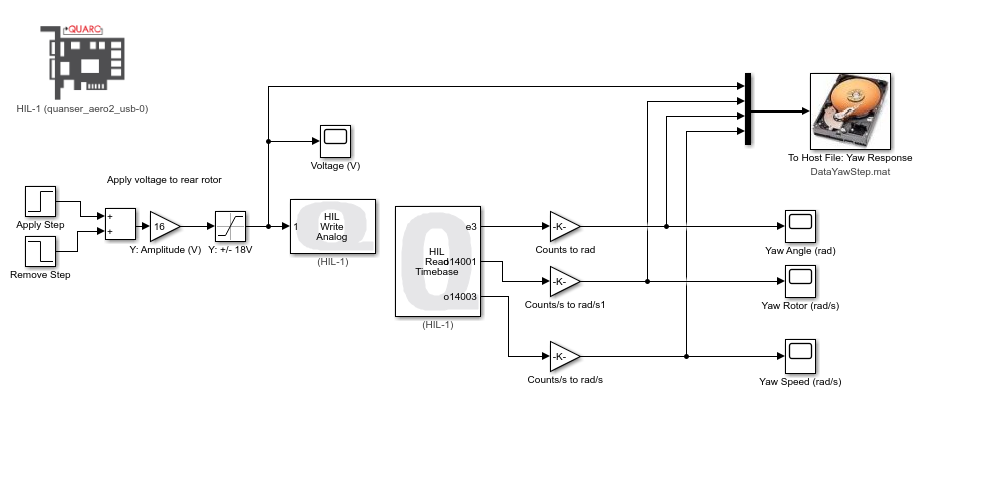

The Simulink model uses the `HIL Write Analog `and `HIL Read Timebase `blocks from the *QUARC Targets *library to apply a voltage to rear yaw rotor and measure the corresponding yaw angle and rate response. The response is saved into a MATLAB *.mat files using the `To Host File `block. This can then be used to plot the results and perform the parameter estimation analysis. 

Build and run the following Simulink model in QUARC by clicking on the *Monitor & Tune* button.

% Load Simulink model
open("q_aero2_yaw_step.slx");

Figure 2 shows the yaw angle response and applied voltage in the scopes. 

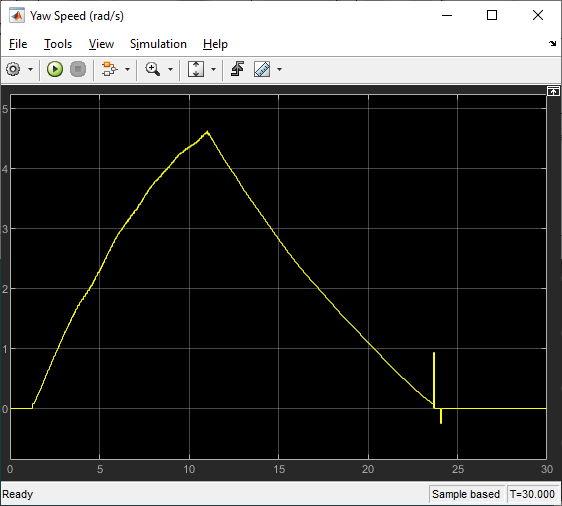 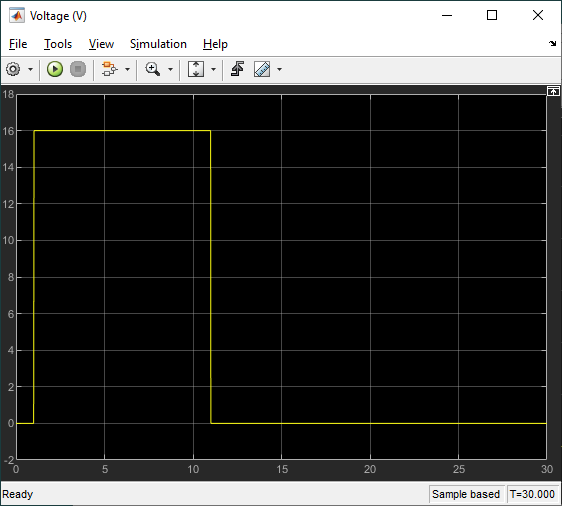

Figure 2 - Yaw angle rate response from applying a step to the rear yaw rotor. 

Plot measured response

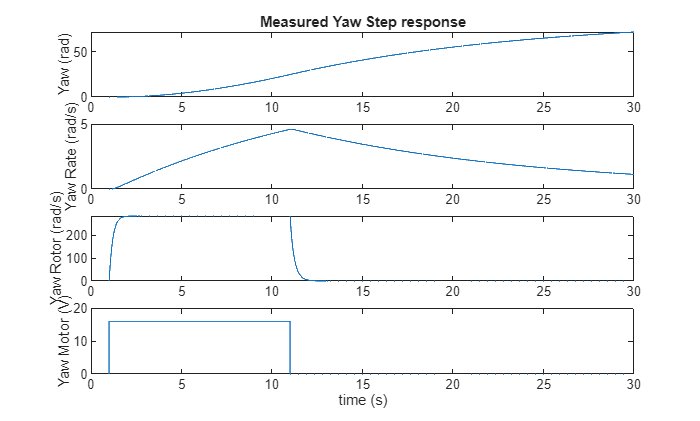

% Load measured data from past run
load("DataYawStep.mat");
% store in variables
t = DataYawStep(1,:); % time (s)
Vy = DataYawStep(2,:); % yaw/rear motor voltage (V)
wm_y = DataYawStep(3,:); % rotor speed (rad/s)
psi = DataYawStep(4,:); % yaw angle (rad)
psi_dot = DataYawStep(5,:);  % yaw rate (rad)
figure;
subplot(4,1,1);
plot(t,psi);
title('Measured Yaw Step response');
ylabel('Yaw (rad)');
subplot(4,1,2);
plot(t,psi_dot);
ylabel('Yaw Rate (rad/s)');
subplot(4,1,3);
plot(t,wm_y);
ylabel('Yaw Rotor (rad/s)');
subplot(4,1,4);
plot(t,Vy);
ylabel('Yaw Motor (V)');
xlabel('time (s)');

### Lab 2: Parameter Estimation

The thrust force gain can be found from the step response and the damping can be found from the free-oscillation response (i.e., after the step is applied). 

#### Finding the Damping

In terms of angular rate, the equation of motion of the yaw becomes


$$J_y \dot{\beta}(t) + D_y \beta(t) = 0$$


where $\beta(t) = \dot{\psi}(t)$. Taking its Laplace transform 


$$J_p (\beta(s) s - \beta(0^-)) + D_y \beta(s)  = 0$$


and solving for the speed we get

$\beta(s) = \frac{J_y} {J_y s + D_y} \beta(0^-) = \frac{J_y/D_y} {J_y/D_y s + 1} \beta(0^-)$.

The yaw free-oscillation transfer function matches the prototype first-order transfer function. Based on the measured time constant of the response, its damping can be found with


$$D_y = \frac{J_y}{\tau}$$


#### First-Order Response

To find the time constant from first-order response from an step as depicted in in Figure 1, find the time it takes for the response to reach $e^{-1}$ or 37% of its final steady-state value.

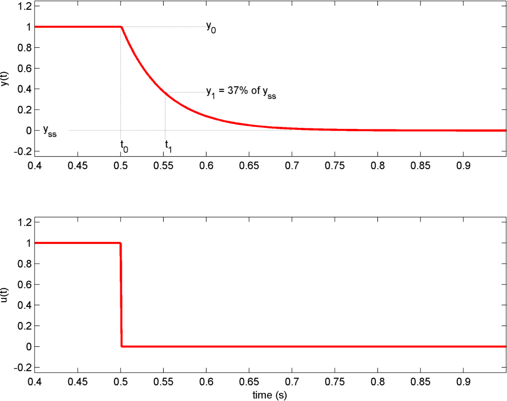

Figure 1: First-order step decaying response 
 

In this case we need to find


$$\begin{array}{ll} 	y(t_1) = y_1 = e^{-1} (y_0 - y_{ss})\\ \end{array}$$
 

and the time constant is $\tau=t_1-t_0$ .

% Voltage applied (V)
Vy0 = max(Vy);
% time when step stops (s)
tstop = 11; 
% sampling interval (s)
h = 0.002;  
% index when step stops
istop = ceil(tstop/h)+1; 
% yaw rate at end of step (rad/s)
w0 = psi_dot(istop);
w_3db = exp(-1)*w0; % 36% of initial value
i_3db = find(psi_dot > w_3db, 1, 'last' ); 
t_3db = i_3db * h;
tau_y = t_3db-tstop; % time constant (s)
Dy = Jy/tau_y

Dy = 0.0018

#### Find the Thrust Gain

The equation of motion when applying a step voltage to the rear/yaw rotor is 


$$J_y \dot{\beta} + D_y \beta = K_{yy} D_t V_y$$


Solving for the thrust gain parameter 


$$K_{yy} =\frac{J_y \dot{\beta} + D_y \beta}{D_tV_y}$$


We can find the thrust gain from the measure yaw rate and derived acceleration 

% Sampling interval of controller (s)
h = 0.002;
% Yaw acceleration from yaw rate measurement (rad/s^2)
psi_ddot = diff(psi_dot)/h;
% Thrust gain (N/V)
Kyy = ( Jy*psi_ddot(1:istop) + Dy*psi_dot(1:istop) ) / ( Dt*Vy(1:istop) )

Kyy = 0.0057

The identified damping and yaw thrust gain are: $D_y = 0.00334$ N-m/(rad/s) and $K_{yy}=0.0074$N/V.